Viewing and plotting the raw waveforms

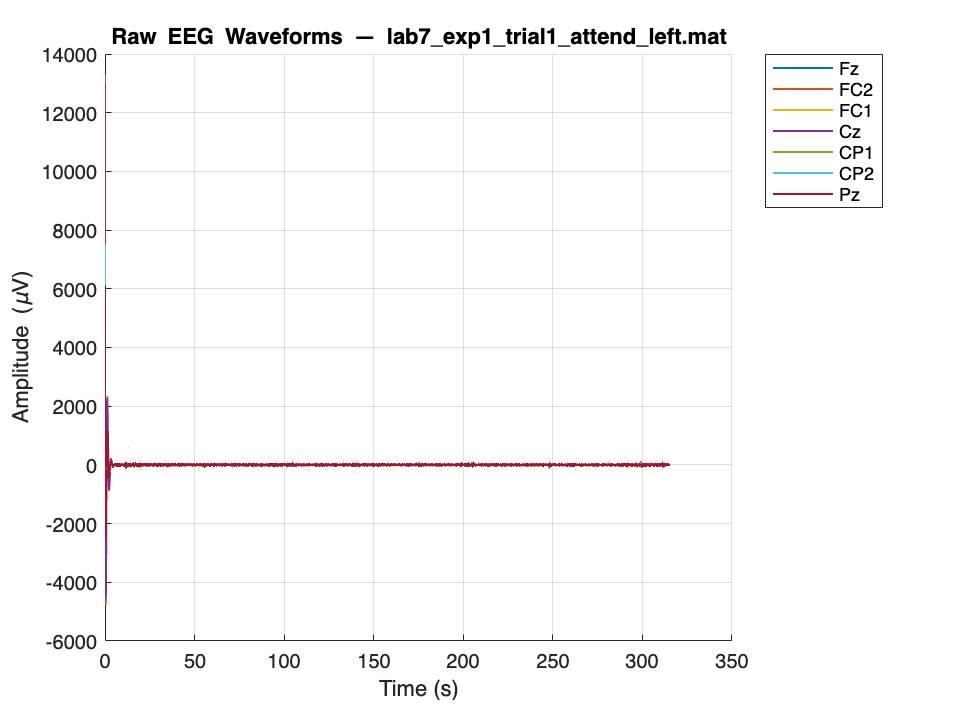

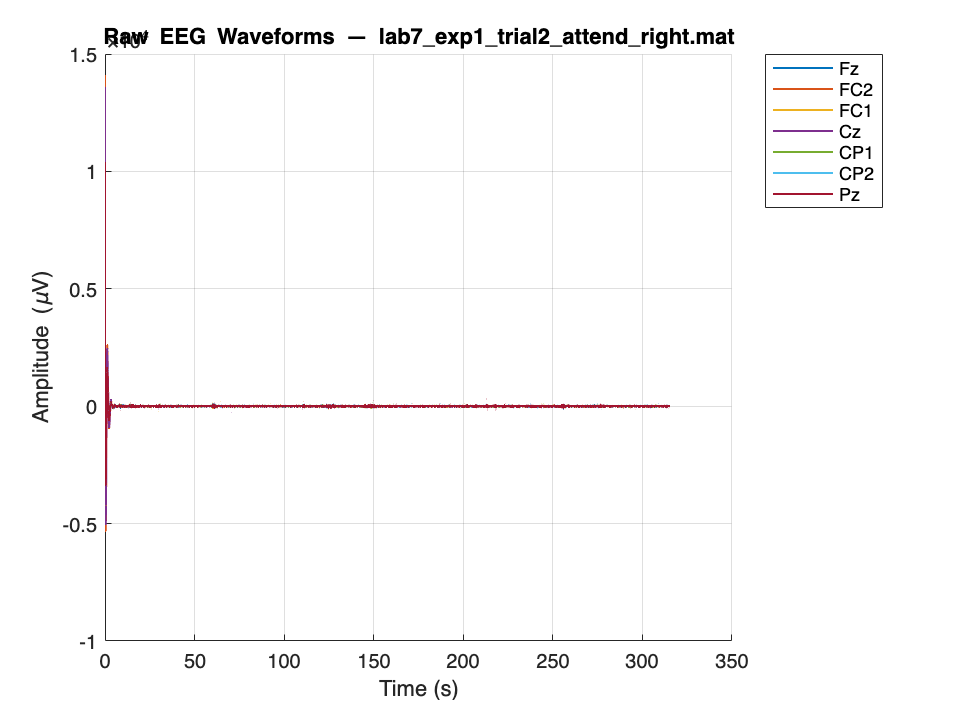

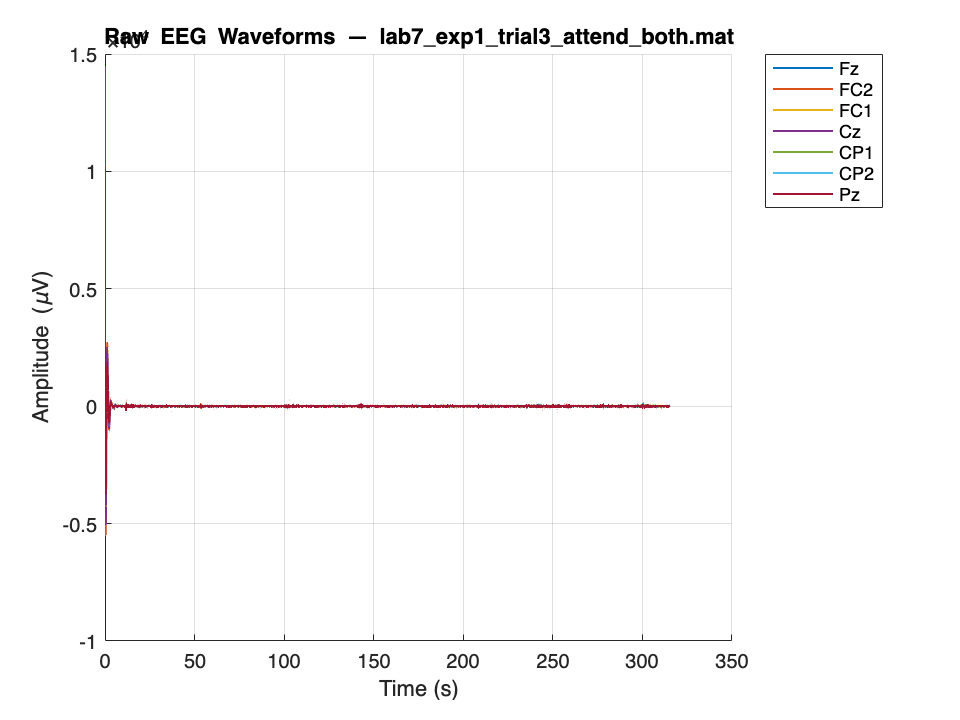

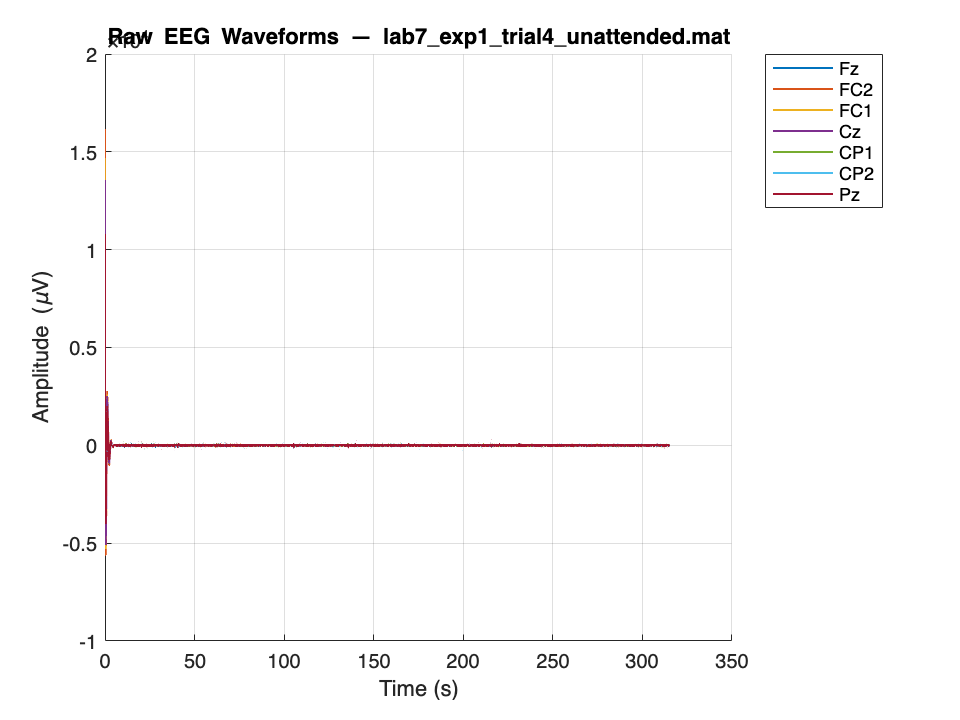

%% Lab 7 — Plot Raw EEG Waveforms (all channels per recording)

files = { ...
  'lab7_exp1_trial1_attend_left.mat', ...
  'lab7_exp1_trial2_attend_right.mat', ...
  'lab7_exp1_trial3_attend_both.mat', ...
  'lab7_exp1_trial4_unattended.mat'};

chanNames = {'Fz','FC2','FC1','Cz','CP1','CP2','Pz'};  

for f = 1:numel(files)
    S = load(files{f});

    % find the timeseries variable
    fn = fieldnames(S);
    ts = [];
    for k = 1:numel(fn)
        if isa(S.(fn{k}), 'timeseries'), ts = S.(fn{k}); break; end
    end
    assert(~isempty(ts), 'No timeseries variable found.');

    y = ts.Data';     % transpose so channels x time
    t = ts.Time';     % seconds

    % first 7 columns are EEG, last is trigger
    EEG = y(1:7, :);

    % remove DC drift
    for i = 1:size(EEG,1)
        EEG(i,:) = detrend(EEG(i,:), 'constant');
    end

    % plot all channels together
    figure('Color','w');
    hold on;
    for i = 1:size(EEG,1)
        plot(t, EEG(i,:), 'LineWidth', 1);
    end
    hold off;

    xlabel('Time (s)');
    ylabel('Amplitude (\muV)');
    title(['Raw EEG Waveforms — ' strrep(files{f}, '_', '\_')]);
    legend(chanNames, 'Location', 'bestoutside');
    grid on;
end

There is a lot of startup effects in the first couple of seconds in the recordings. Shouldn't be a problem, since the first 15 seconds is offset for primarily that purpose <- to get rid of the artifacts. 

**Plot the time waveform of the sounds used in your experiments (only the first**

**100ms of the signal, separately for the left ear and the right ear) and their**

**time-frequency decomposition called a spectrogram (use specgram function in**

**MATLAB). (1 pt)**

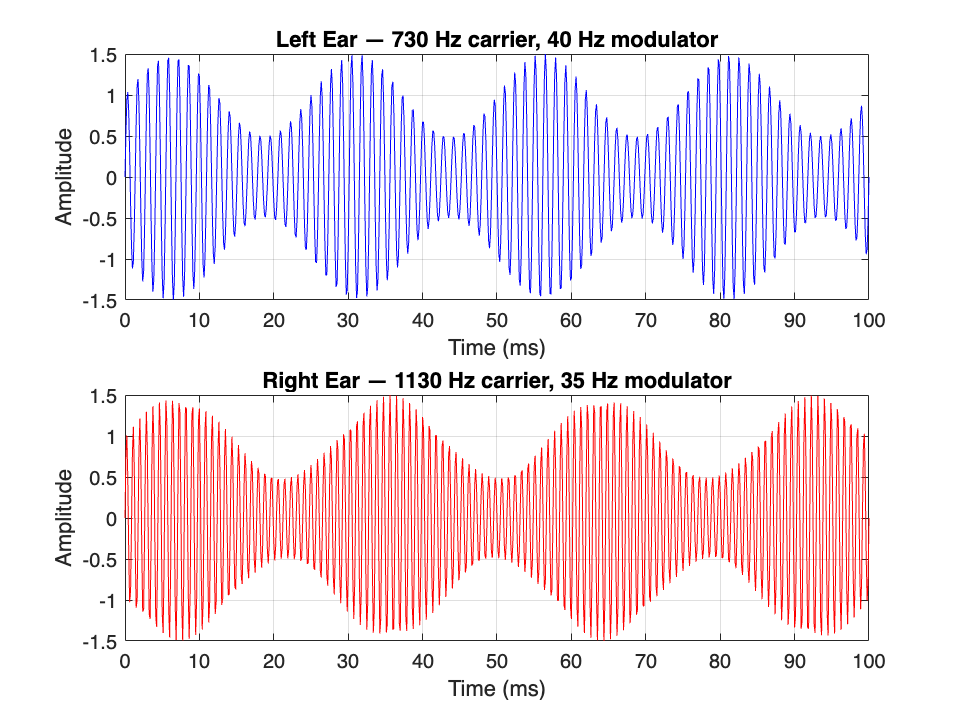

%% HW Q1 — Fixed spectrogram display
fs = 8000;
dur = 1;
t = (0:1/fs:dur)';

fc_left = 730;  fm_left = 40;
fc_right = 1130; fm_right = 35;

left  = (1 + 0.5*sin(2*pi*fm_left*t)) .* sin(2*pi*fc_left*t);
right = (1 + 0.5*sin(2*pi*fm_right*t)) .* sin(2*pi*fc_right*t);

idx100ms = t <= 0.1;

% ---- Waveforms ----
figure('Color','w');
subplot(2,1,1);
plot(t(idx100ms)*1000, left(idx100ms), 'b');
xlabel('Time (ms)'); ylabel('Amplitude');
title('Left Ear — 730 Hz carrier, 40 Hz modulator'); grid on;

subplot(2,1,2);
plot(t(idx100ms)*1000, right(idx100ms), 'r');
xlabel('Time (ms)'); ylabel('Amplitude');
title('Right Ear — 1130 Hz carrier, 35 Hz modulator'); grid on;

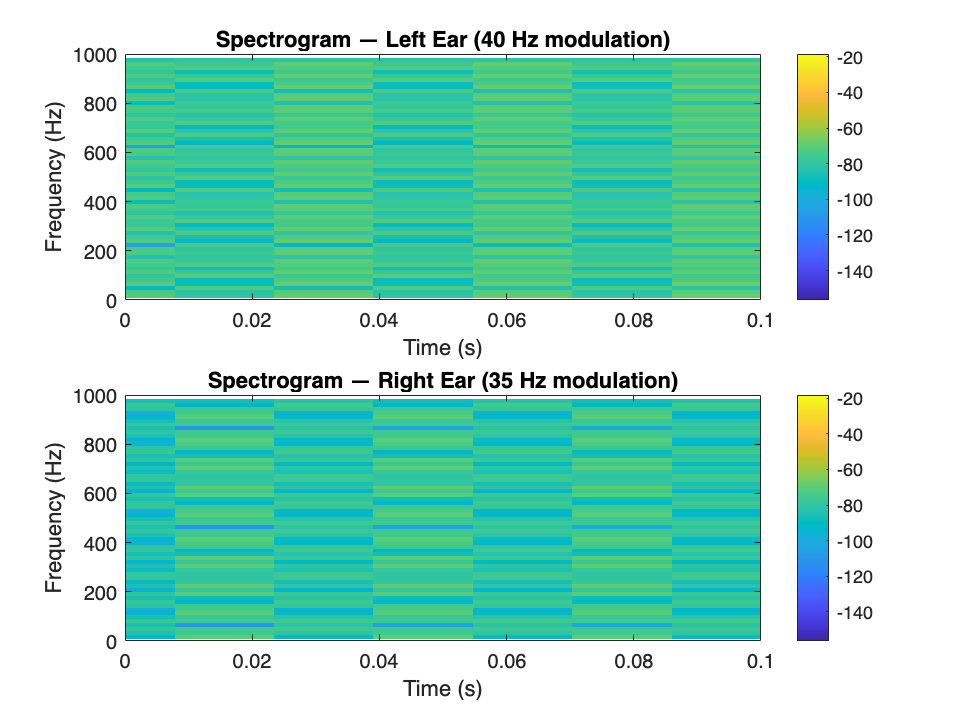


% ---- Spectrograms ----
figure('Color','w');
subplot(2,1,1);
spectrogram(left,256,128,512,fs);          % remove 'yaxis'
ylim([0 1000]);                            % show 0–2 kHz
xlim([0 0.1]);
xlabel('Time (s)'); ylabel('Frequency (Hz)');
title('Spectrogram — Left Ear (40 Hz modulation)'); colorbar;

subplot(2,1,2);
spectrogram(right,256,128,512,fs);
ylim([0 1000]);
xlim([0 0.1]);
xlabel('Time (s)'); ylabel('Frequency (Hz)');
title('Spectrogram — Right Ear (35 Hz modulation)'); colorbar;

**Load the EEG signal in Matlab. Use the trigger signal from the s-function to**

**separate the EEG response to sound. (1 pt)**

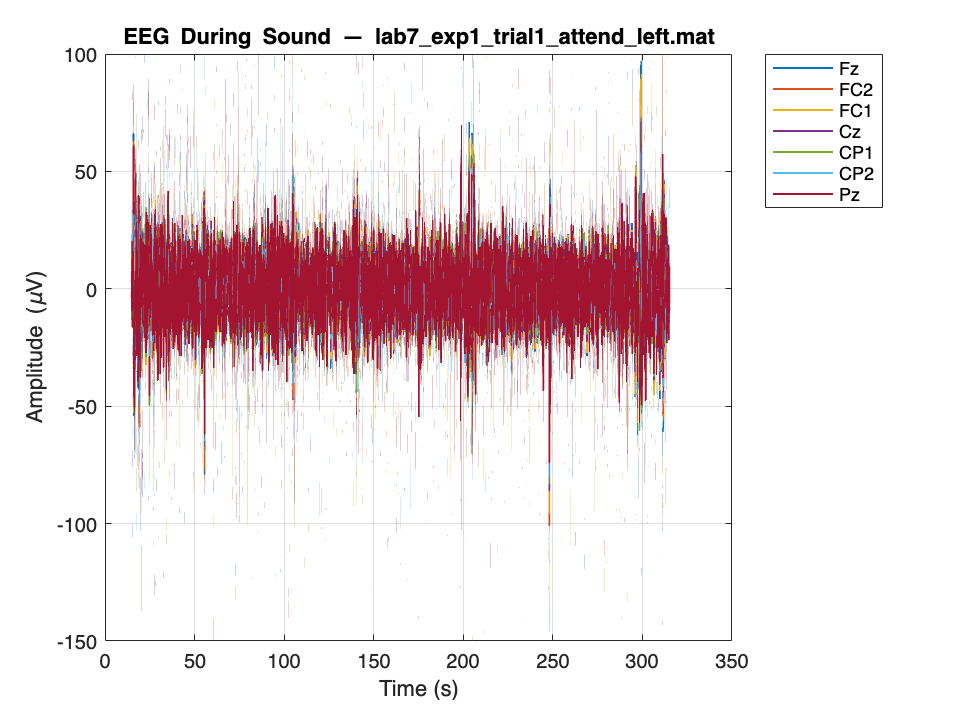

lab7_exp1_trial1_attend_left.mat: duration 300.0 s, Fs ≈ 352.00 Hz


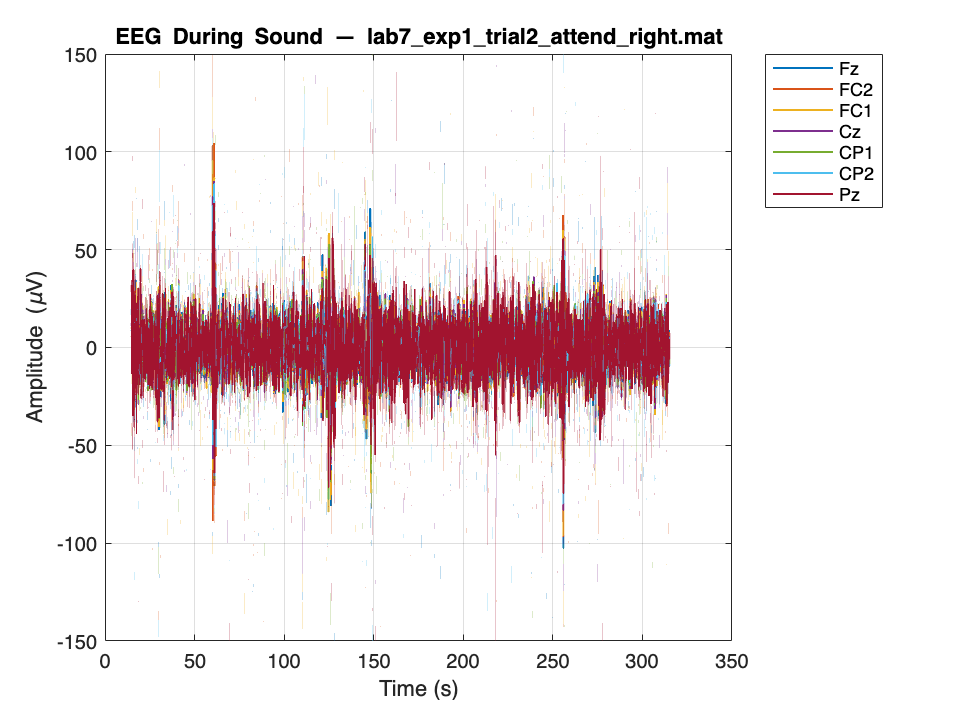

lab7_exp1_trial2_attend_right.mat: duration 300.0 s, Fs ≈ 352.00 Hz


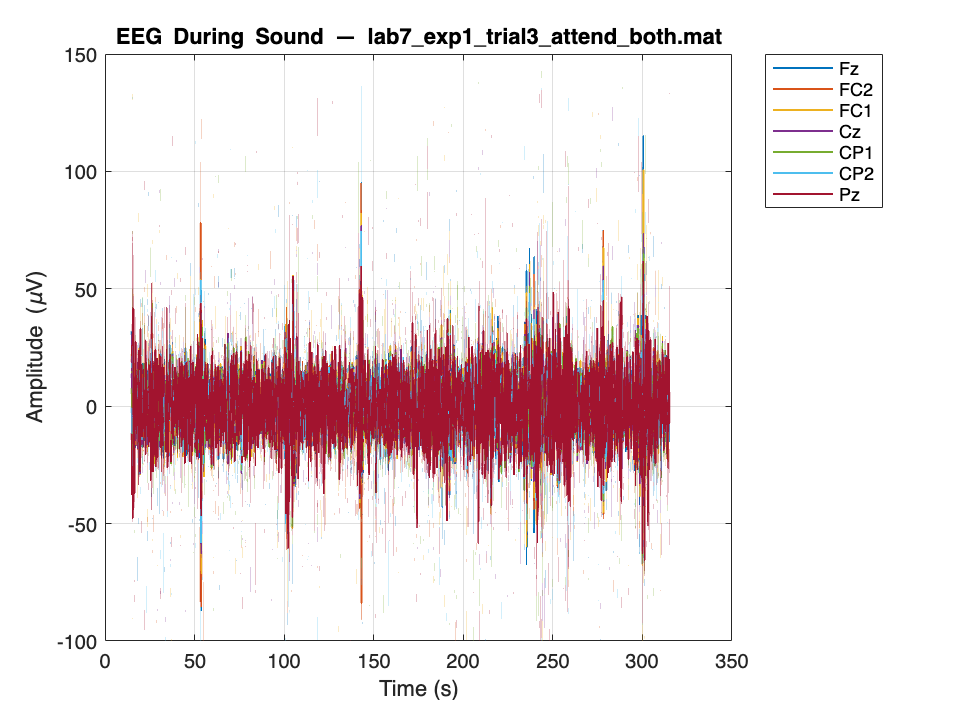

lab7_exp1_trial3_attend_both.mat: duration 300.0 s, Fs ≈ 352.00 Hz


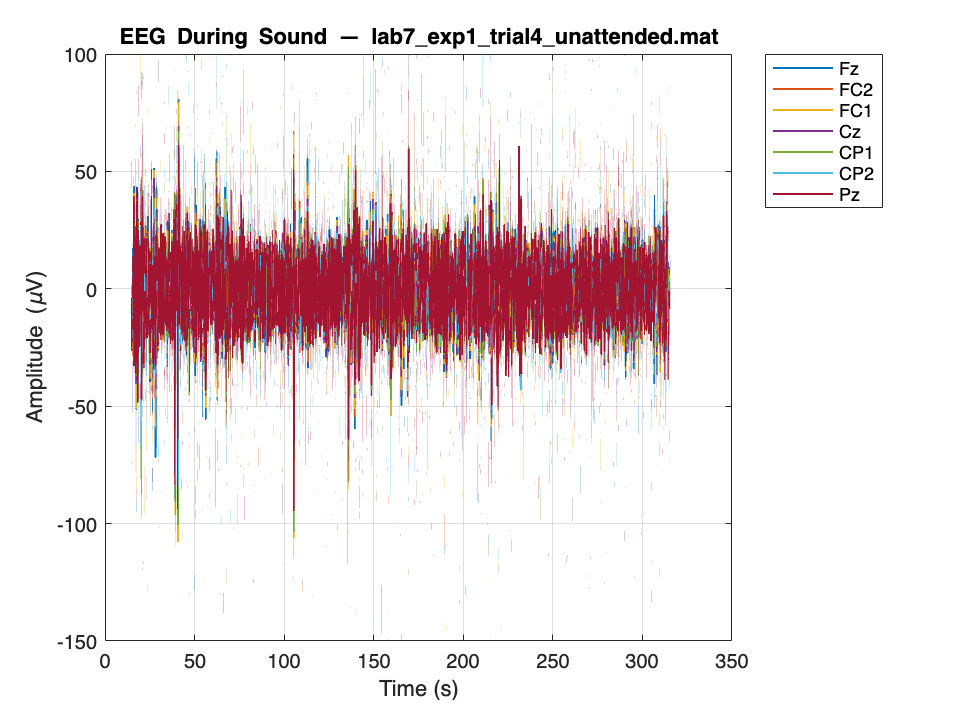

lab7_exp1_trial4_unattended.mat: duration 300.0 s, Fs ≈ 352.00 Hz


%% HW Q2 — Extract EEG during sound (trigger = 1) for all trials

files = { ...
  'lab7_exp1_trial1_attend_left.mat', ...
  'lab7_exp1_trial2_attend_right.mat', ...
  'lab7_exp1_trial3_attend_both.mat', ...
  'lab7_exp1_trial4_unattended.mat'};

chanNames = {'Fz','FC2','FC1','Cz','CP1','CP2','Pz'};

for f = 1:numel(files)
    S = load(files{f});

    % find timeseries variable
    fn = fieldnames(S);
    ts = [];
    for k = 1:numel(fn)
        if isa(S.(fn{k}), 'timeseries'), ts = S.(fn{k}); break; end
    end
    assert(~isempty(ts), 'No timeseries variable found.');

    t = ts.Time(:);
    data = ts.Data;
    EEG = data(:,1:7);
    trigger = data(:,8);

    % only keep samples where sound was playing
    active = trigger > 0.5;
    t_sound = t(active);
    EEG_sound = EEG(active,:);

    % remove DC offset from each channel
    for i = 1:size(EEG_sound,2)
        EEG_sound(:,i) = detrend(EEG_sound(:,i),'constant');
    end

    % plot EEG for sound period only
    figure('Color','w');
    plot(t_sound, EEG_sound, 'LineWidth', 1);
    xlabel('Time (s)');
    ylabel('Amplitude (\muV)');
    title(['EEG During Sound — ' strrep(files{f}, '_', '\_')]);
    legend(chanNames, 'Location', 'bestoutside');
    grid on;

    % print basic info
    fprintf('%s: duration %.1f s, Fs ≈ %.2f Hz\n', ...
        files{f}, t_sound(end)-t_sound(1), 1/mean(diff(t)));
end

Take the Fourier transform of each channel, and then average the magnitude

of FFT over all channels. (1 pt)

Fs = 352

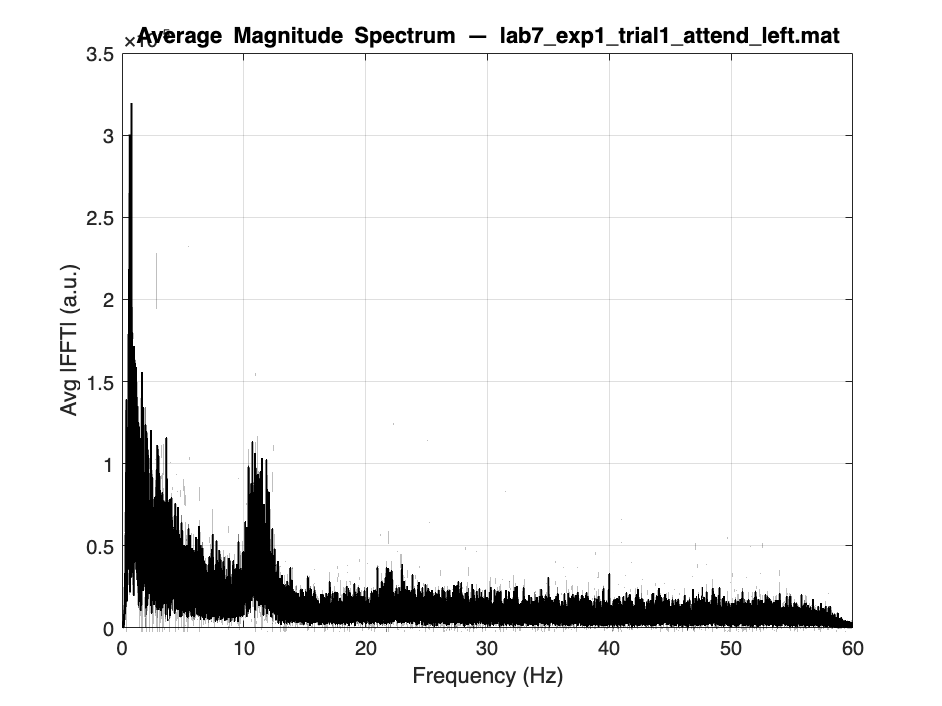

lab7_exp1_trial1_attend_left.mat: N=105601, Fs=352.000 Hz, df=0.00333 Hz


Fs = 352

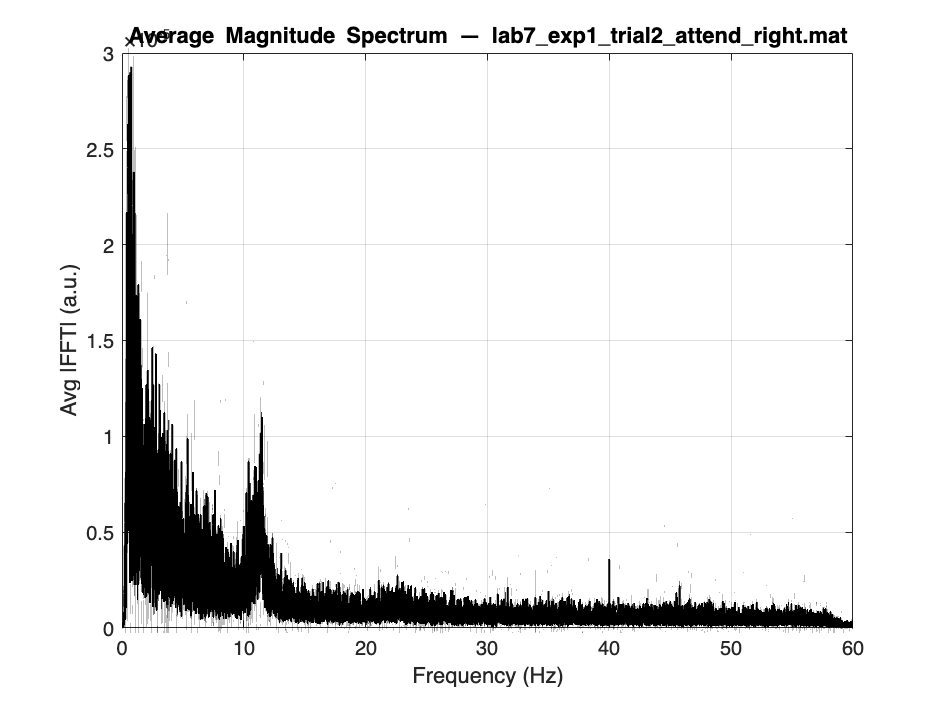

lab7_exp1_trial2_attend_right.mat: N=105601, Fs=352.000 Hz, df=0.00333 Hz


Fs = 352

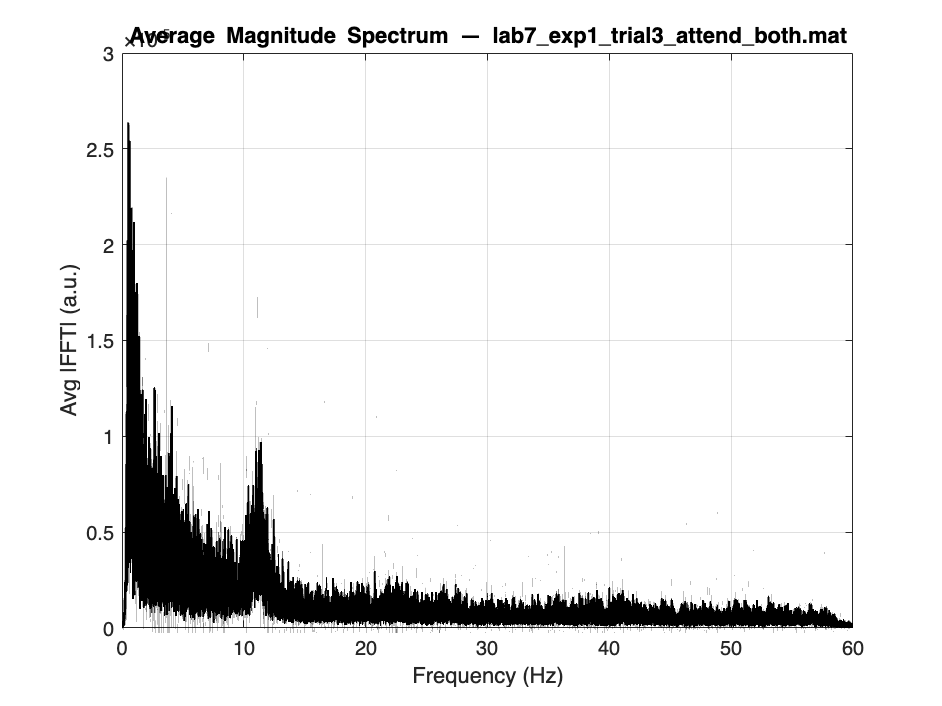

lab7_exp1_trial3_attend_both.mat: N=105601, Fs=352.000 Hz, df=0.00333 Hz


Fs = 352

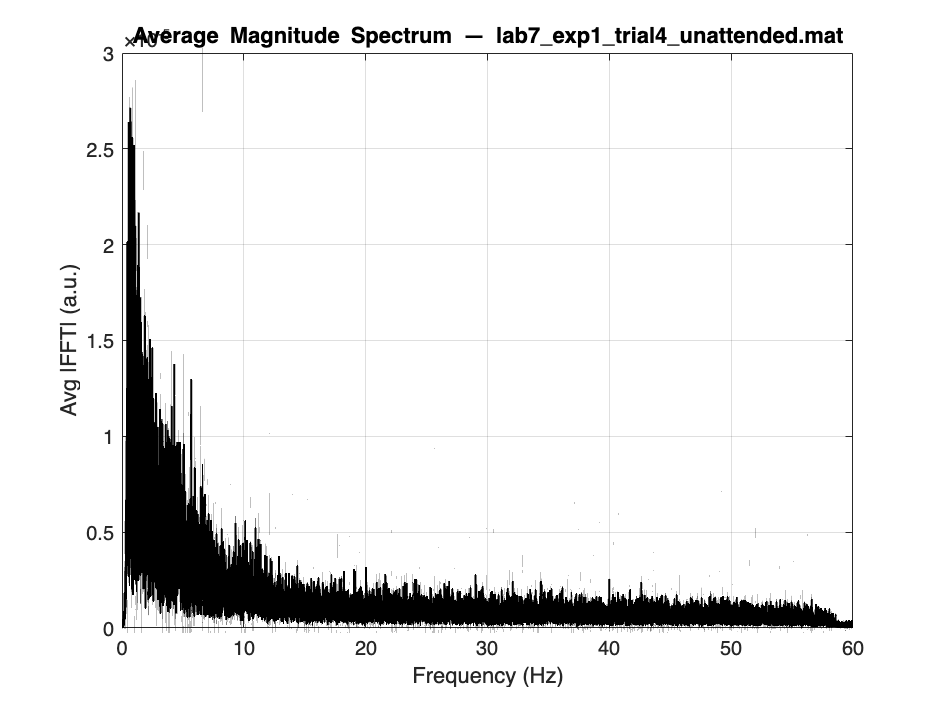

lab7_exp1_trial4_unattended.mat: N=105601, Fs=352.000 Hz, df=0.00333 Hz


%% HW Q3 — Average magnitude |FFT| over channels (0–60 Hz view)

files = { ...
  'lab7_exp1_trial1_attend_left.mat', ...
  'lab7_exp1_trial2_attend_right.mat', ...
  'lab7_exp1_trial3_attend_both.mat', ...
  'lab7_exp1_trial4_unattended.mat'};

for f = 1:numel(files)
    S = load(files{f});

    % --- pick the timeseries with at least 8 columns (7 EEG + trigger)
    cand = struct2cell(S);
    ix = cellfun(@(x) isa(x,'timeseries') && size(x.Data,2) >= 8, cand);
    ts = cand{find(ix,1)};
    assert(~isempty(ts),'No valid EEG timeseries found.');

    t  = ts.Time(:);
    X  = ts.Data;          % [N x 8]
    EEG = X(:,1:7);        % 7 EEG channels
    trg = X(:,8) > 0.5;    % trigger mask (sound on)

    % --- keep only sound-on samples
    t   = t(trg);
    EEG = EEG(trg,:);

    % --- sampling rate and detrend
    Fs = 352%1/median(diff(t));
    EEG = detrend(EEG,'constant');

    % --- FFT settings
    N = size(EEG,1);
    K = floor(N/2)+1;          % one-sided length
    w = hann(N,'periodic');    % window
    W = sum(w)/2;              % amplitude correction for one-sided spectrum
    df = Fs/N;
    faxis = (0:K-1)'*df;

    % --- per-channel magnitude spectrum, then average over channels
    A = zeros(K, size(EEG,2));
    for c = 1:size(EEG,2)
        Xc = fft(EEG(:,c).*w);
        P1 = abs(Xc(1:K)) / (W*N);   % scale to preserve amplitudes
        if K > 2, P1(2:end-1) = 2*P1(2:end-1); end
        A(:,c) = P1;
    end
    Aavg = mean(A, 2);  % average magnitude across channels

    % --- plot 0–60 Hz
    figure('Color','w');
    rng = faxis <= 60;
    plot(faxis(rng), Aavg(rng), 'k','LineWidth',1);
    grid on; xlabel('Frequency (Hz)'); ylabel('Avg |FFT| (a.u.)');
    title(['Average Magnitude Spectrum — ' strrep(files{f}, '_','\_')]);
    fprintf('%s: N=%d, Fs=%.3f Hz, df=%.5f Hz\n', files{f}, N, Fs, df);
end

Question: if the length of the FFT is L, and given the sampling frequency of

your EEG signal (256Hz), what samples in FFT correspond to the modulator

frequencies of the left ear and the right ear? (i.e. 40Hz & 35Hz)? (1 pt)

%% HW Q4 — Identify FFT bin indices for 35 Hz and 40 Hz modulators

% Given parameters
Fs = 352;                  % sampling frequency of EEG (Hz)
mods = [35, 40];           % modulation frequencies of interest (Hz)

% Suppose your FFT (from the previous question) used length L samples:
L = size(EEG,1);           % number of samples per FFT (insert actual number if run separately)

% Frequency resolution (spacing between FFT bins)
df = Fs / L;

% Bin indices (1-based)
bins = round(mods / df) + 1;

fprintf('Sampling frequency = %.1f Hz, FFT length = %d\n', Fs, L);

Sampling frequency = 352.0 Hz, FFT length = 105601


fprintf('Frequency resolution = %.6f Hz/bin\n', df);

Frequency resolution = 0.003333 Hz/bin


fprintf('FFT bin for 35 Hz = %d\n', bins(1));

FFT bin for 35 Hz = 10501


fprintf('FFT bin for 40 Hz = %d\n', bins(2));

FFT bin for 40 Hz = 12001



%% --- Sanity check: reverse the calculation ---
% Verify that these bins indeed correspond to ≈35 Hz and 40 Hz

f_from_35 = (bins(1)-1) * df;
f_from_40 = (bins(2)-1) * df;

fprintf('\nSanity check (bin → frequency):\n');


Sanity check (bin → frequency):


fprintf('Bin %d → %.3f Hz (expected ≈ 35 Hz)\n', bins(1), f_from_35);

Bin 10501 → 35.000 Hz (expected ≈ 35 Hz)


fprintf('Bin %d → %.3f Hz (expected ≈ 40 Hz)\n', bins(2), f_from_40);

Bin 12001 → 40.000 Hz (expected ≈ 40 Hz)


Create a table or bar graph showing the average magnitude of the ASSR

signal over all channels for the two modulator frequencies and for each of the

four listening conditions. How do you interpret the data? (6 pts)

%% HW Q5 — ASSR magnitude @ 35 & 40 Hz across conditions (Fs ≈ 352 Hz)

files = { ...
  'lab7_exp1_trial1_attend_left.mat', ...
  'lab7_exp1_trial2_attend_right.mat', ...
  'lab7_exp1_trial3_attend_both.mat', ...
  'lab7_exp1_trial4_unattended.mat'};

conds   = {'Attend-Left','Attend-Right','Attend-Both','Unattended'};
targets = [35 40];      % Hz
band    = 0.5;          % ±Hz window
ASSR    = nan(numel(files), numel(targets));

for fi = 1:numel(files)                      % <- loop index renamed
    S = load(files{fi});

    % select timeseries with >=8 columns
    cand = struct2cell(S);
    ix = cellfun(@(x) isa(x,'timeseries') && size(x.Data,2) >= 8, cand);
    ts = cand{find(ix,1)};

    t  = ts.Time(:);
    X  = ts.Data;
    EEG = X(:,1:7);
    trg = X(:,8) > 0.5;

    Fs = 1/median(diff(t));
    i0 = find(trg,1,'first'); t0 = t(i0);
    keep = trg & t >= (t0 + 100) & t <= (t0 + 300);
    t = t(keep); EEG = detrend(EEG(keep,:),'constant');

    % Welch PSD 0–60 Hz
    [pxx,freq] = pwelch(EEG, hann(round(4*Fs)), round(2*Fs), 0:0.05:60, Fs);
    P = mean(pxx, 2, 'omitnan');             % avg across channels

    % band means at 35 and 40 Hz
    for j = 1:numel(targets)
        idx = freq >= (targets(j)-band) & freq <= (targets(j)+band);
        ASSR(fi,j) = mean(P(idx), 'omitnan');
    end

    fprintf('%s  Fs=%.3f Hz, analyzed %.1f s\n', files{fi}, Fs, (t(end)-t(1)));
end

lab7_exp1_trial1_attend_left.mat  Fs=284.444 Hz, analyzed 200.0 s
lab7_exp1_trial2_attend_right.mat  Fs=284.444 Hz, analyzed 200.0 s
lab7_exp1_trial3_attend_both.mat  Fs=284.444 Hz, analyzed 200.0 s
lab7_exp1_trial4_unattended.mat  Fs=284.444 Hz, analyzed 200.0 s


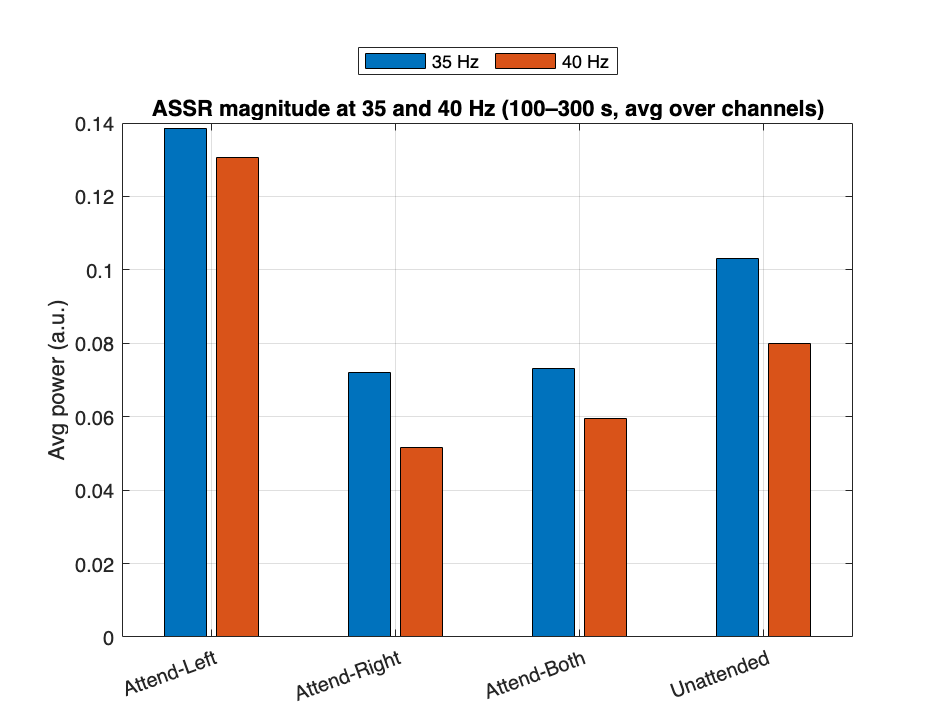


figure('Color','w');
bar(ASSR);
set(gca,'XTickLabel',conds,'XTickLabelRotation',20);
ylabel('Avg power (a.u.)');
legend({'35 Hz','40 Hz'},'Location','northoutside','Orientation','horizontal');
title('ASSR magnitude at 35 and 40 Hz (100–300 s, avg over channels)'); grid on;


T = array2table(ASSR, 'VariableNames', {'Hz35','Hz40'}, 'RowNames', conds);
disp(T);

                      Hz35        Hz40  
                    ________    ________

    Attend-Left      0.13856     0.13064
    Attend-Right    0.071974    0.051551
    Attend-Both     0.073219    0.059456
    Unattended       0.10298    0.079814



The 35 Hz and 40 Hz peaks reflect the auditory steady-state responses entrained by the right and left ear modulators, respectively. While the pattern is modest, the data suggest slightly higher 35 Hz power when attending to the right ear, consistent with attentional enhancement of the corresponding modulation frequency. The unexpectedly high amplitudes in the unattended condition likely stem from reduced motion or fatigue-related variability rather than true attentional gain.